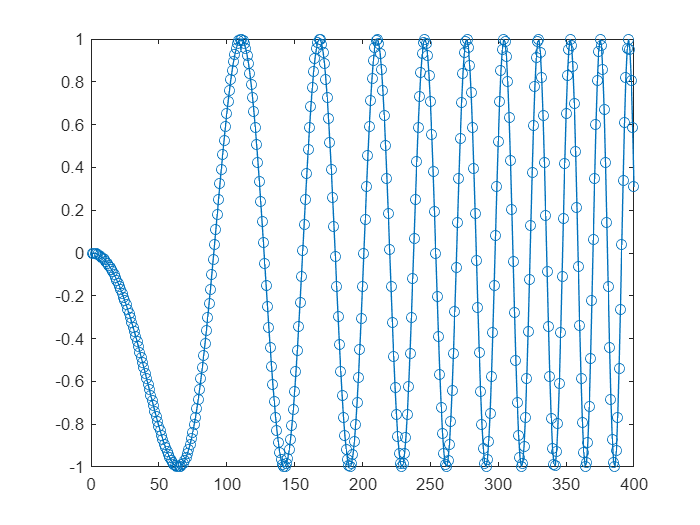

hchirp = dsp.Chirp( ...
    'InitialFrequency', 0,...
    'TargetFrequency', 2, ...
    'TargetTime', 10, ...
    'SweepTime', 400, ...
    'SampleRate', 40, ...
    'SamplesPerFrame', 400, ...
    'InitialPhase', pi/2);

chirpData = (step(hchirp))';
% evenFlag = mod(minute(datetime('now')),2);
% if evenFlag
%     chirpData = fliplr(chirpData);
% end

plot(chirpData, '-o');


u = int16(round(chirpData*4096))

u = 1×400 int16 row vector
       0      -2      -6     -14     -26     -40     -58     -79    -103    -130    -161    -195    -231    -272    -315    -361    -411    -464    -520    -579    -641    -706    -774    -845    -919    -995   -1075   -1157   -1241   -1328   -1418   -1509   -1603   -1699   -1796   -1895   -1996   -2097   -2200   -2304   -2408   -2512   -2616   -2720   -2823   -2925   -3025   -3124   -3221   -3315


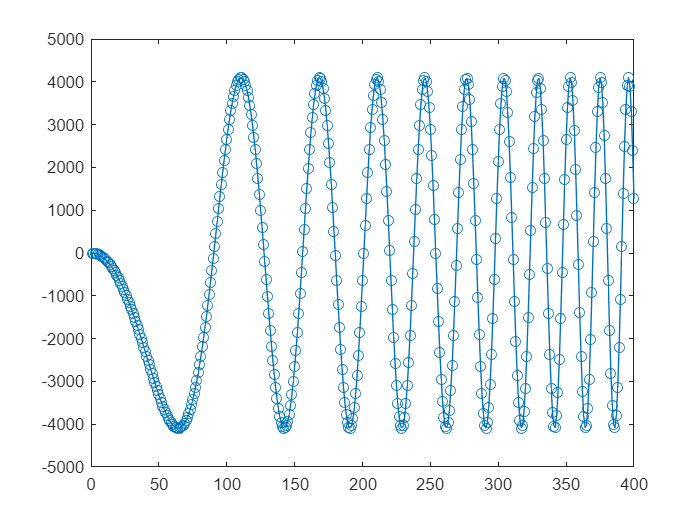


plot(u, '-o');